
d = 6

d = 6


syms x y
syms a b
syms h
E(x,y,a,b,h) = h^2/((x-d*a)^2+(y-d*b)^2+h^2)^2

$$E(x, y, a, b, h) = \frac{h^{2}}{{\left({\left(6\,a-x\right)}^{2}+{\left(6\,b-y\right)}^{2}+h^{2}\right)}^{2}}$$


E_rec = symsum(symsum(E,a,-1,1),b,-1,1)

$$E\_rec(x, y, h) = \frac{h^{2}}{{\left({\left(x-6\right)}^{2}+{\left(y-6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x-6\right)}^{2}+{\left(y+6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x+6\right)}^{2}+{\left(y-6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x+6\right)}^{2}+{\left(y+6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left(h^{2}+x^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x-6\right)}^{2}+h^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x+6\right)}^{2}+h^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}$$

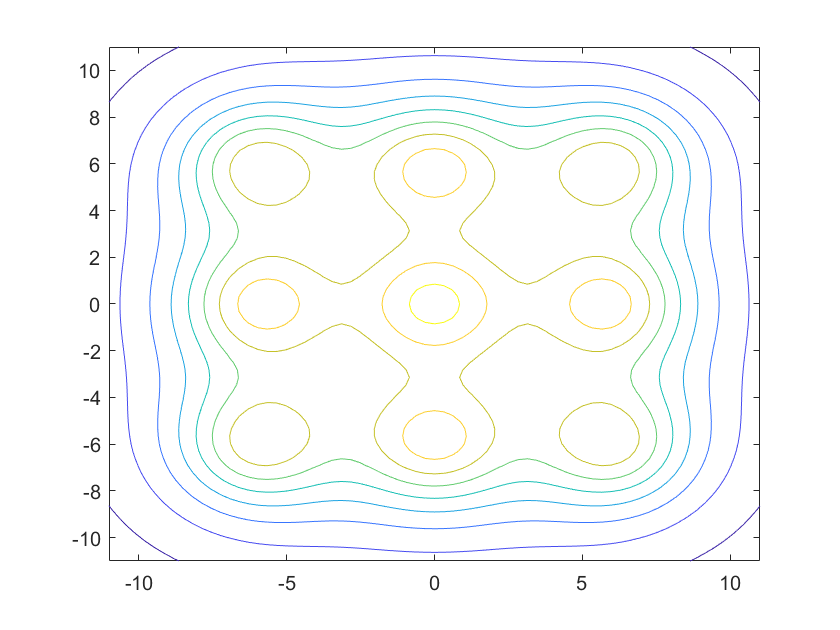


%ezsurf(E_rec(x,y,4),[-11,11])


fcontour(E_rec(x,y,4),[-11,11])

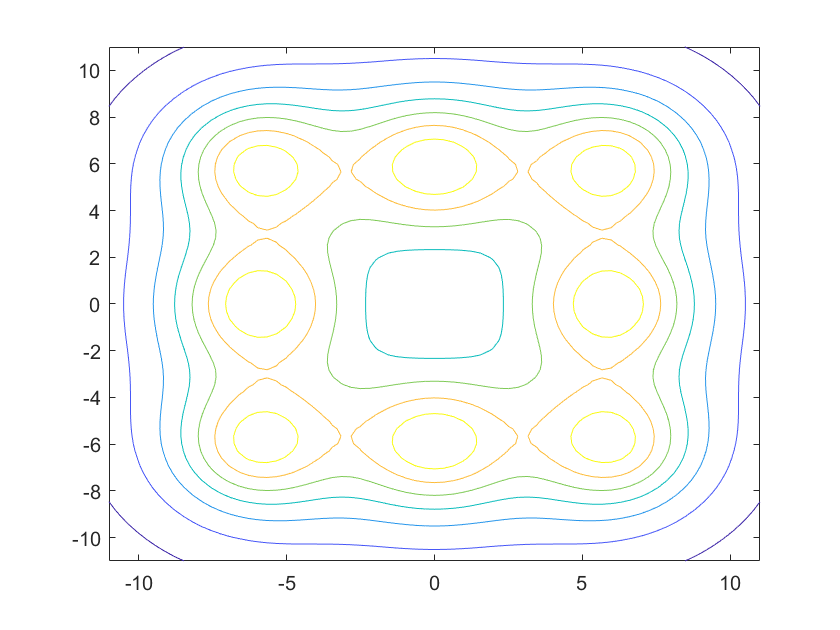

fcontour(E_rec(x,y,4)-E(x,y,0,0,4),[-11,11])

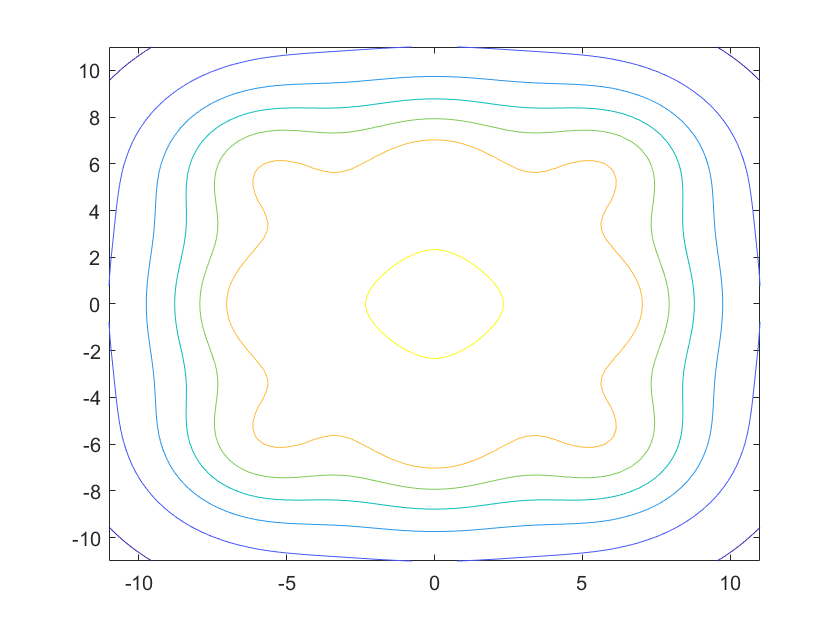

fcontour(E_rec(x,y,5),[-11,11])

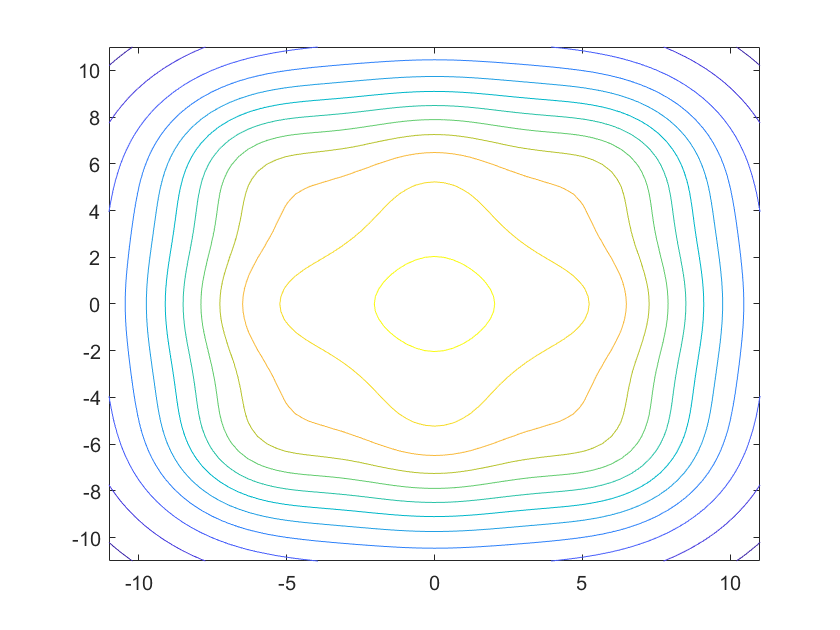

fcontour(E_rec(x,y,6),[-11,11])


syms k

E_hex(x,y,h) = E(x,y,0,0,h) + symsum(E(x,y,cos(k*pi/3+pi/6),sin(k*pi/3+pi/6),h),k,0,5)

$$E\_hex(x, y, h) = \begin{array}{l} \frac{h^{2}}{{\left(h^{2}+x^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-3\right)}^{2}+h^{2}+\sigma_{1}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-3\right)}^{2}+h^{2}+\sigma_{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+3\right)}^{2}+h^{2}+\sigma_{1}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+3\right)}^{2}+h^{2}+\sigma_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(x-3\,\sqrt{3}\right)}^{2}\\ \sigma_{2}={\left(x+3\,\sqrt{3}\right)}^{2} \end{array}$$

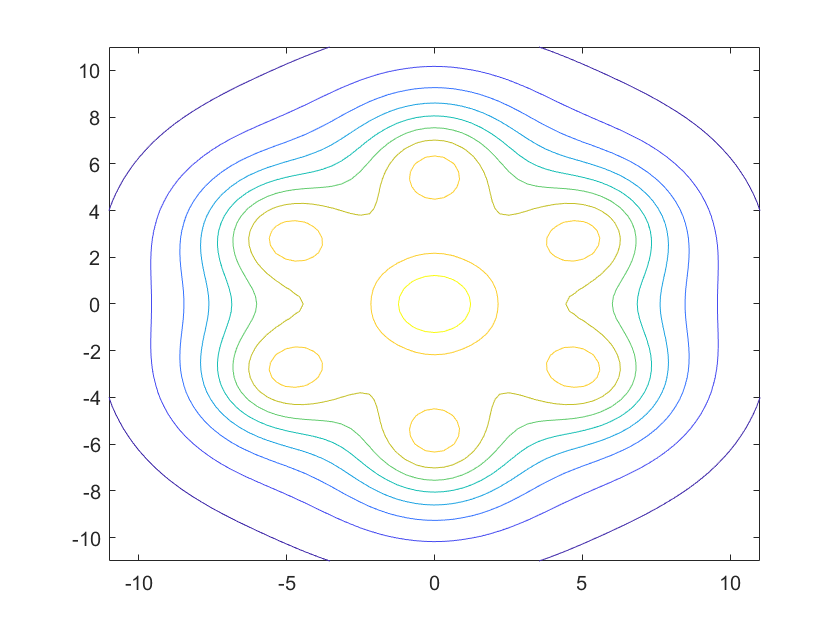


%ezsurf(E_hex(x,y,4),[-11,11])

fcontour(E_hex(x,y,4),[-11,11])

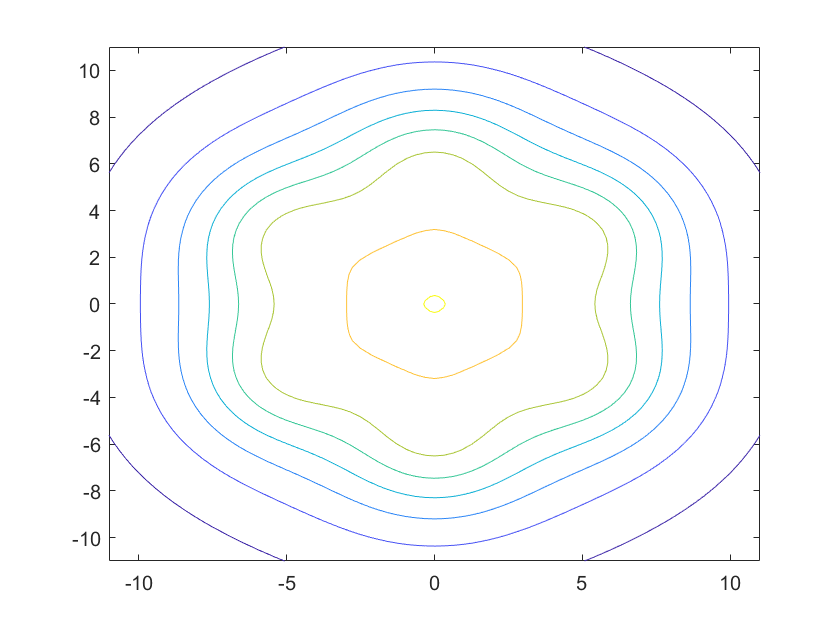

fcontour(E_hex(x,y,5),[-11,11])

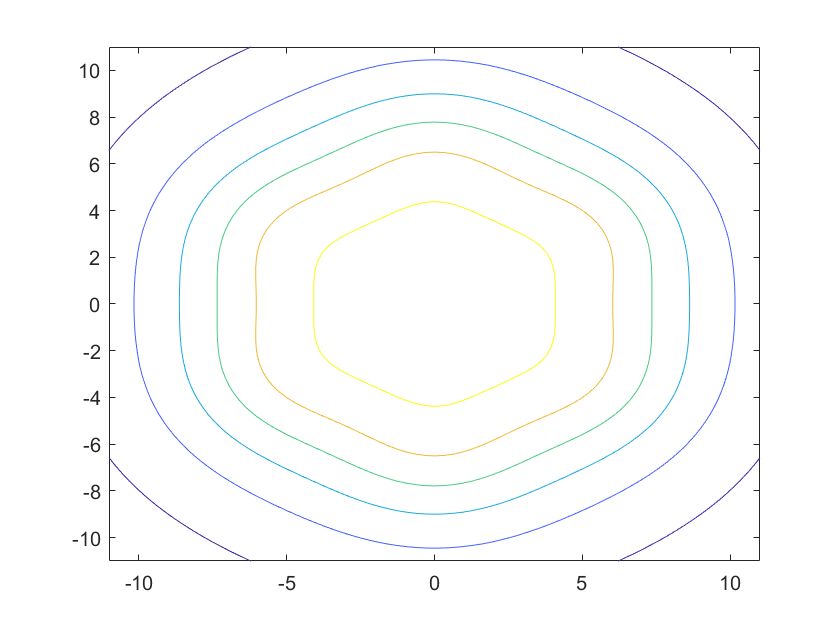

fcontour(E_hex(x,y,6),[-11,11])


E1 = E(0,0,0,0,4)

$$E1 = \frac{1}{16}$$

E_rmax = E_rec(0,0,4)

$$E\_rmax = \frac{30897}{327184}$$


Kr = E_rmax/(E_rmax-E1)

$$Kr = \frac{30897}{10448}$$


E_hmax = E_hex(0,0,4)

$$E\_hmax = \frac{265}{2704}$$

Kh = E_hmax/(E_hmax-E1)

$$Kh = \frac{265}{96}$$